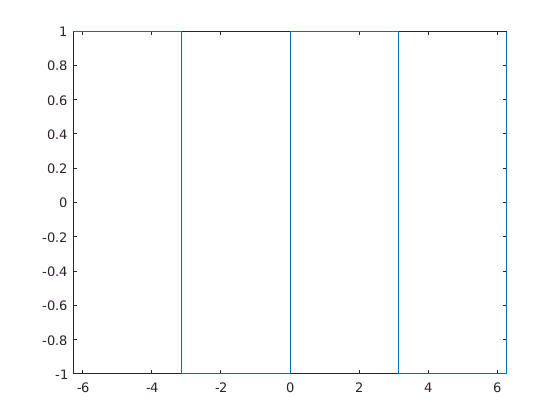

terms=[5 10 20 40 80 160 320 640];
syms x;
f=(-1)^floor(x/pi);
fplot(f,[-2*pi,2*pi])

syms n;
L=2*pi;
coeff=int(f*exp(-1i*n*2*pi*x/L),x,-L/2,L/2)/L

$$coeff = -\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}\,{\left({\mathrm{e}}^{\pi \,n\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}^{2}\,\mathrm{i}}{2\,n\,\pi }$$

transform=coeff*exp(1i*2*pi*n*x/L)

$$transform = -\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}\,{\mathrm{e}}^{n\,x\,\mathrm{i}}\,{\left({\mathrm{e}}^{\pi \,n\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}^{2}\,\mathrm{i}}{2\,n\,\pi }$$

ranges=[];
for i=terms
    tmp=[];
    parfor j=-floor(i/2):floor(i/2)
        if j==0
            continue
        end
        tmp=[tmp subs(transform,n,j)];
    end
    ranges=[ranges sum(tmp)];
end

$$ranges = \frac{2\,{\mathrm{e}}^{-x\,\mathrm{i}}\,\mathrm{i}}{\pi }-\frac{2\,{\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}}{\pi }$$

$$ranges = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1}-\sigma_{2} & \sigma_{1}-\sigma_{2}+\frac{2\,{\mathrm{e}}^{-3\,x\,\mathrm{i}}\,\mathrm{i}}{3\,\pi }-\frac{2\,{\mathrm{e}}^{3\,x\,\mathrm{i}}\,\mathrm{i}}{3\,\pi }+\frac{2\,{\mathrm{e}}^{-5\,x\,\mathrm{i}}\,\mathrm{i}}{5\,\pi }-\frac{2\,{\mathrm{e}}^{5\,x\,\mathrm{i}}\,\mathrm{i}}{5\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,{\mathrm{e}}^{-x\,\mathrm{i}}\,\mathrm{i}}{\pi }\\ \sigma_{2}=\frac{2\,{\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}}{\pi } \end{array}$$

$$ranges = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1}-\sigma_{2} & \sigma_{1}-\sigma_{2}+\sigma_{4}-\sigma_{6}+\sigma_{3}-\sigma_{5} & \sigma_{1}-\sigma_{2}+\sigma_{4}-\sigma_{6}+\sigma_{3}-\sigma_{5}+\frac{2\,{\mathrm{e}}^{-7\,x\,\mathrm{i}}\,\mathrm{i}}{7\,\pi }-\frac{2\,{\mathrm{e}}^{7\,x\,\mathrm{i}}\,\mathrm{i}}{7\,\pi }+\frac{2\,{\mathrm{e}}^{-9\,x\,\mathrm{i}}\,\mathrm{i}}{9\,\pi }-\frac{2\,{\mathrm{e}}^{9\,x\,\mathrm{i}}\,\mathrm{i}}{9\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,{\mathrm{e}}^{-x\,\mathrm{i}}\,\mathrm{i}}{\pi }\\ \sigma_{2}=\frac{2\,{\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}}{\pi }\\ \sigma_{3}=\frac{2\,{\mathrm{e}}^{-5\,x\,\mathrm{i}}\,\mathrm{i}}{5\,\pi }\\ \sigma_{4}=\frac{2\,{\mathrm{e}}^{-3\,x\,\mathrm{i}}\,\mathrm{i}}{3\,\pi }\\ \sigma_{5}=\frac{2\,{\mathrm{e}}^{5\,x\,\mathrm{i}}\,\mathrm{i}}{5\,\pi }\\ \sigma_{6}=\frac{2\,{\mathrm{e}}^{3\,x\,\mathrm{i}}\,\mathrm{i}}{3\,\pi } \end{array}$$

$$ranges = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}-\sigma_{6} & \sigma_{3}-\sigma_{6}+\sigma_{2}-\sigma_{5}+\sigma_{1}-\sigma_{4} & \sigma_{3}-\sigma_{6}+\sigma_{2}-\sigma_{5}+\sigma_{1}-\sigma_{4}+\sigma_{8}-\sigma_{10}+\sigma_{7}-\sigma_{9} & \sigma_{3}-\sigma_{6}+\sigma_{2}-\sigma_{5}+\sigma_{1}-\sigma_{4}+\sigma_{8}-\sigma_{10}+\sigma_{7}-\sigma_{9}+\frac{2\,{\mathrm{e}}^{-11\,x\,\mathrm{i}}\,\mathrm{i}}{11\,\pi }-\frac{2\,{\mathrm{e}}^{11\,x\,\mathrm{i}}\,\mathrm{i}}{11\,\pi }+\frac{2\,{\mathrm{e}}^{-13\,x\,\mathrm{i}}\,\mathrm{i}}{13\,\pi }-\frac{2\,{\mathrm{e}}^{13\,x\,\mathrm{i}}\,\mathrm{i}}{13\,\pi }+\frac{2\,{\mathrm{e}}^{-15\,x\,\mathrm{i}}\,\mathrm{i}}{15\,\pi }-\frac{2\,{\mathrm{e}}^{15\,x\,\mathrm{i}}\,\mathrm{i}}{15\,\pi }+\frac{2\,{\mathrm{e}}^{-17\,x\,\mathrm{i}}\,\mathrm{i}}{17\,\pi }-\frac{2\,{\mathrm{e}}^{17\,x\,\mathrm{i}}\,\mathrm{i}}{17\,\pi }+\frac{2\,{\mathrm{e}}^{-19\,x\,\mathrm{i}}\,\mathrm{i}}{19\,\pi }-\frac{2\,{\mathrm{e}}^{19\,x\,\mathrm{i}}\,\mathrm{i}}{19\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,{\mathrm{e}}^{-5\,x\,\mathrm{i}}\,\mathrm{i}}{5\,\pi }\\ \sigma_{2}=\frac{2\,{\mathrm{e}}^{-3\,x\,\mathrm{i}}\,\mathrm{i}}{3\,\pi }\\ \sigma_{3}=\frac{2\,{\mathrm{e}}^{-x\,\mathrm{i}}\,\mathrm{i}}{\pi }\\ \sigma_{4}=\frac{2\,{\mathrm{e}}^{5\,x\,\mathrm{i}}\,\mathrm{i}}{5\,\pi }\\ \sigma_{5}=\frac{2\,{\mathrm{e}}^{3\,x\,\mathrm{i}}\,\mathrm{i}}{3\,\pi }\\ \sigma_{6}=\frac{2\,{\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}}{\pi }\\ \sigma_{7}=\frac{2\,{\mathrm{e}}^{-9\,x\,\mathrm{i}}\,\mathrm{i}}{9\,\pi }\\ \sigma_{8}=\frac{2\,{\mathrm{e}}^{-7\,x\,\mathrm{i}}\,\mathrm{i}}{7\,\pi }\\ \sigma_{9}=\frac{2\,{\mathrm{e}}^{9\,x\,\mathrm{i}}\,\mathrm{i}}{9\,\pi }\\ \sigma_{10}=\frac{2\,{\mathrm{e}}^{7\,x\,\mathrm{i}}\,\mathrm{i}}{7\,\pi } \end{array}$$

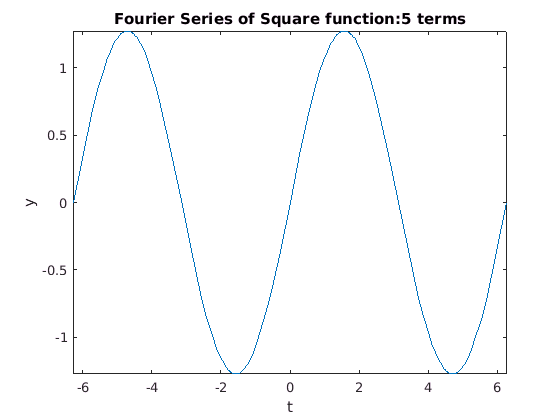

fig=figure;

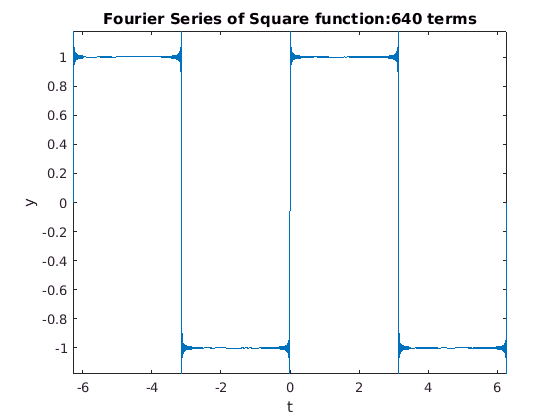

filename='animation_series.gif';
for i=1:length(ranges)
    fplot(real(ranges(i)),[-2*pi,2*pi]);
    title(strcat('Fourier Series of Square function:',string(terms(i)),' terms'));
    xlabel('t');
    ylabel('y');
    drawnow;
    frame=getframe(fig);
    im=frame2im(frame);
    [imidx,cm]=rgb2ind(im,256);
    if i==1
        imwrite(imidx,cm,filename,'gif','Loopcount',inf);
    else
        imwrite(imidx,cm,filename,'gif','WriteMode','append');
    end
end